# Introduction to YALMIP

Finn Vehlhaber and Leonardo Pedroso

In these exercises we learn how to formulate different classes of optimization problems such that they can be parsed by YALMIP. This live script makes reference to the **Exercise 1** in the handout.

**Run the sections one by one by clicking into the respective code window and hitting "Run Section". Sentences highlighted in bold give instructions on how to complete the given code. Code lines like this need to be completed by you:**

% ----- complete code here
% (incomplete code here)
% -----

Clean up script

clear; close all; clc

### I. Linear Programming

Consider Problem 1 in the handout. 

**Complete the constraints in the code given below**

yalmip('clear');
% optimization variables
x1 = sdpvar(1,1);
x2 = sdpvar(1,1);

% constraints
constraints = [
    2 * x1 + x2 >= 1
% ----- complete code here
    x1 + 3 *x2 >= 1
    x1 >= 0
    x2 >= 0
% -----
];

objective = x1 + x2;

opts = sdpsettings('solver','linprog','verbose',2);

optimize(constraints,objective,opts);

Plot

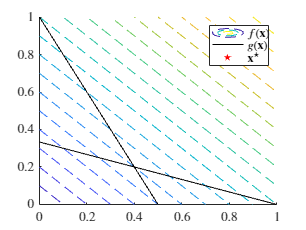

x1vector = 0:.5:2;
x2vector = 0:.5:2;
figure;
hold on
% objective function
contour(x1vector,x2vector,x1vector'*ones(1,5) + ones(5,1) * x2vector,0:0.1:2,'--','DisplayName','$f(\mathbf{x})$')
% constraints
plot(x1vector,1 - 2*x1vector,'k','HandleVisibility','off');
plot(x1vector,1/3 - x1vector/3,'k','DisplayName','$g(\mathbf{x})$');
scatter(value(x1),value(x2),200,'r','filled','pentagram','DisplayName','$\mathbf{x}^\star$')
hold off
xlim([0 1])
ylim([0 1])
legend('Interpreter','latex','Location','northeast')
set(gca,'ticklabelinterpreter','latex')

### II. Quadratic Programming

Consider Problem 2 in the handout. 

**Complete the constraints in the code given below**

yalmip('clear');
% optimization variables
x1 = sdpvar(1,1);
x2 = sdpvar(1,1);

% constraints
constraints = [
    2 * x1 + x2 <= 10
% ----- complete code here
    x1 + x2 <= 8
    x1 <= 4
% -----
];

objective = (x1 -5)^2 + (x2-5)^2;

opts = sdpsettings('solver','quadprog','verbose',2);

optimize(constraints,objective,opts);

MOSEK Version 10.1.26 (Build date: 2024-2-21 13:35:17)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : QO (quadratic optimization problem)
  Constraints            : 3               
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 2               
  Matrix variables       : 0               
  Integer variables      : 0               

Optimizer started.
Quadratic to conic reformulation started.
Quadratic to conic reformulation terminated. Time: 0.00    
Optimizer terminated. Time: 0.01    


Interior-point solution summary
  Problem status  : PRIMAL_AND_DUAL_FEASIBLE
  Solution status : OPTIMAL
  Primal.  obj: -4.4999999994e+01   nrm: 1e+01    Viol.  con: 3e-09    var: 0e+00  
  Dual.    obj: -4.4999999984e+01   nrm: 2e+00    Viol

Plot

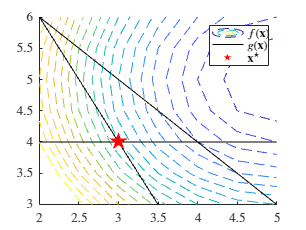

x1vector = 0:.5:10;
x2vector = 0:.5:10;
figure;
hold on
% objective function
contour(x1vector,x2vector,(x1vector - 5).^2'*ones(1,21) + ones(21,1) * (x2vector - 5).^2,0:0.5:10,'--','DisplayName','$f(\mathbf{x})$')
% constraints
plot(x1vector,10 - 2*x1vector,'k','DisplayName','$g(\mathbf{x})$');
plot(x1vector,8 - x1vector,'k','HandleVisibility','off');
plot(x1vector, 4 + 0*x1vector,'k','HandleVisibility','off');
scatter(value(x1),value(x2),200,'r','filled','pentagram','DisplayName','$\mathbf{x}^\star$')
hold off
xlim([2 5])
ylim([3 6])
legend('Interpreter','latex','Location','northeast')
set(gca,'ticklabelinterpreter','latex')

### **III. Semidefinite Programming**

Use Yalmip and semidefinite programming to find the ellipse $\mathcal{E}= \{ x \,| x^T P^{-1} x \leq 1 \}$in $\mathbb{R}^2$ with the greatest area centered at $$(0,0)$$ that inscribed in a polytope $\mathcal{H} = \{ x \, | \, Ax+b \leq 0\}$

% Define constraints of the politope in the form Ax+b<=0
% ----- complete code here
A = [-2 0; 1 4; 2 2; 1 0; -2 10];
b = [-2; -5; -4; -2; 8];
% -----

% Setup YALMIP 
yalmip('clear');
P = sdpvar(2);
constraints = []


constraints =

     []




% Define constraints
for i = 1:size(A,1)
% ----- complete code here
    constraints = [constraints,...
        A(i,:)*P*A(i,:)' - b(i).^2 <= 0 
        ];
% -----    
end

% Define objective
% ----- complete code here
objective = - logdet(P)

Logdet-term 1x1



% Solve SDP
opts = sdpsettings('solver','mosek','verbose',2); 
optimize(constraints,objective,opts);

 
Objective c'x-sum logdet(P_i) has been changed to c'x-sum det(P_i)^(1/(2^ceil(log2(length(P_i))))).
This is not an equivalent transformation. You should use SDPT3 which supports MAXDET terms
See the MAXDET section in the manual for details.
 

MOSEK Version 10.1.26 (Build date: 2024-2-21 13:35:17)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 7               
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 1               
  Scalar variables       : 8               
  Matrix variables       : 1 (scalarized: 10)
  Integer variables      : 0               

Optimizer started.
Presolve started.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Linear dependency checker started.
Linea

P = value(P)

P =     1.0000    0.2001
    0.2001    0.6800


Set up the semidefinite program maximizing the volume of $\mathcal{E}$ subject to the rectangular constraints in Yalmip


$$\min -\log \det P \text{ s.t. } [A]_i P [A]_i^T-b_i^2 \leq 0, \ \forall i $$


*Hint: Yalmip provides a dedicated concave *`logdet `*function*

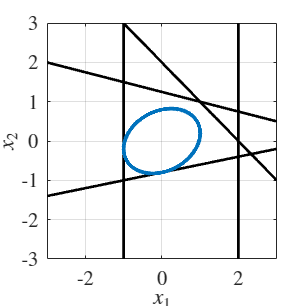

figure('Position',4*[0 0 144 144]); % Nice aspect ratio for double column
hold on;
grid on;
box on;
set(gca,'FontSize',15);
set(gca,'TickLabelInterpreter','latex') % Latex style axis
% Plot linear constraints
x_points = -3:0.1:3;
for i = 1:size(A,1)
    if abs(A(i,2))>eps(1)
        plot(x_points,-(A(i,1)/A(i,2))*x_points-b(i)/A(i,2),'-k','LineWidth',2);
    else
        plot(-b(i)/A(i,1)*[1 1],[-3 3],'-k','LineWidth',2);
    end
end
% Plot solution
Npoints = 1000;
theta = 0:2*pi/(Npoints-1):2*pi;
y = zeros(2,Npoints);
x = zeros(2,Npoints);
y(1,:) = cos(theta);
y(2,:) = sin(theta);
[S,D] = eig(inv(P));
T = S/sqrtm(D);
for i = 1:Npoints
    x(:,i) = T*y(:,i);
end
plot(x(1,:),x(2,:),'LineWidth',3,'Color',[0, 0.4470, 0.7410]);
ylabel('$x_2$','Interpreter','latex');
xlabel('$x_1$','Interpreter','latex');
xlim([-3 3]);
ylim([-3 3]);
hold off;

### IV. Conic Programming

Consider the following optimization problem:


$$\min_\mathbf{x} \;\; (\mathbf{x}-\mathbf{c})^\top (\mathbf{x}-\mathbf{c}) \\
\text{s.t.} \;\;\;\; g_1(\mathbf{x}) = \mathbf{x}^\top A\mathbf{x} \leq 0\\
\qquad \; \, g_2(\mathbf{x}) = -\mathbf{x} \leq 0$$


with A = $\left\lbrack \begin{array}{cc}
3 & -2\\
-2 & 1
\end{array}\right\rbrack$ , c = $\left\lbrack \begin{array}{c}
3\\
0
\end{array}\right\rbrack$, and $\mathbf{x} \in \mathbb{R}^2$.

Find the optimum $\mathbf{x}^\star$ with MOSEK.

A = [3 -2;-2 1];
c = [3;0];


% ----- complete code here
x = sdpvar(2,1)

Linear matrix variable 2x1 (full, real, 2 variables)
Coefficient range: 1 to 1


constraints = [x'*A*x <= 0;
                -x<= 0 ]

+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                                Constraint|   Coefficient range|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (quadratic) 1x1|              1 to 4|
|   #2|               Element-wise inequality 2x1|              1 to 1|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++


objective = (x-c)'*(x-c)

Quadratic scalar (real, 2 variables)
Coefficients range: 1 to 9


% ----- 

opts = sdpsettings('solver','mosek','verbose',2);

optimize(constraints,objective,opts)

ans = struct with fields:
    solvertime: 0
          info: 'Solver not applicable (mosek does not support multi-term monomial equalities)'
       problem: -4
    yalmiptime: 0.0980


value(x)

ans =    NaN
   NaN


What errors do you encounter?

Now, reformulate $g_1(\mathbf{x})$ as a second-order cone and try again. Use vectors $\mathbf{a}$ and $\mathbf{b}$ to construct the cone $| \mathbf{a}^\top \mathbf{x} | \leq \mathbf{b}^\top \mathbf{x}$

*Hint: Yalmip provides a dedicated *`cone `*function. Type *`help cone`* in the command line for the syntax.*

% ----- complete code here
a = [3; -2];
b = [0; 1];
x = sdpvar(2,1);
constraints = [cone(a'*x,b'*x)]

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                         Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Second order cone constraint 2x1|              1 to 3|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++


objective = (x-c)'*(x-c)

Quadratic scalar (real, 2 variables)
Coefficients range: 1 to 9


% ----- 
opts = sdpsettings('solver','mosek','verbose',2);

optimize(constraints,objective,opts)

MOSEK Version 10.1.26 (Build date: 2024-2-21 13:35:17)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 3               
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 2               
  Scalar variables       : 6               
  Matrix variables       : 0               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 2                 time                   : 0.00            
Lin. dep.  - tries                  : 

ans = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '23.2.0.2365128 (R2023b)'
       yalmiptime: 0.1126
       solvertime: 0.0394
             info: 'Successfully solved (MOSEK-CONE)'
          problem: 0


value(x)

ans =     1.5000
    1.5000


Plot

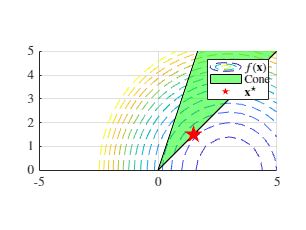

x1vector = -5:.5:5;
x2vector = 0:.5:5;

figure;
hold on
% objective function
contour(x1vector,x2vector,(x2vector).^2'*ones(1,21) + ones(11,1) * (x1vector-3).^2,0:2:30,'--','DisplayName','$f(\mathbf{x})$')
% cone
conePlot2d(a,b); %plots the cone norm(a'*x)<=b'*x
% optimum
scatter(value(x(1)),value(x(2)),200,'r','filled','pentagram','DisplayName','$\mathbf{x}^\star$')
grid on
legend('Interpreter','latex','Location','northeast')
set(gca,'ticklabelinterpreter','latex')
axis equal
xlim([-5 5])
ylim([0 5])

function conePlot2d(a,b)
% plots the cone norm(a'*x)<=b'*x over the interval x1 in [-5,5], x2 in [0,5]
x1vector = -5:.5:5;
coneplot = 0;
switch sign(a(1))*sign(a(2))
    case 1 %i.e., both have the same sign
        g1vector = ( b(1) - abs(a(1)))/(abs(a(2)) - b(2)) * x1vector;
        g2vector = ( b(1) - abs(a(1)))/(abs(a(2)) - b(2)) * x1vector;
        coneplot = 1;
    case -1
        g1vector = (b(1)+abs(a(1)))/(abs(a(2))-b(2)) * x1vector;
        g2vector = (-b(1)+abs(a(1)))/(abs(a(2))+b(2)) * x1vector;
        coneplot = 1;
    case 0
        display("This crappy function was written in a rush and does not support either element of a to be 0");
end
    if coneplot
    % find endpoints for fill
    x1Top = [x1vector(g1vector==max(g1vector)),x1vector(g1vector==max(g2vector))];
    x2Top = [max(g1vector),max(g2vector)];
    
    fill([0 min(x1Top) max(x1Top) 0],[0 min(x2Top) max(x2Top) 0],'green',...
        'FaceAlpha',.5,'EdgeColor','k','DisplayName','Cone')
    xlim([-5 5])
    ylim([0 5])
    end
end